# Example A from Lecture L3b:  built-in spline examples

Let's load some data first: 

clear all; close all; clc
Tin = readtable("2021-02-07--AnnualSeptNorthernSeaIceExtent.txt","ReadVariableNames",true);
% data from https://www.ncdc.noaa.gov/snow-and-ice/extent/sea-ice/N/9 
Year = Tin.Year; 
SExt = Tin.Mkm2; 
yb = [min(Year) max(Year)] % write out for which years we've read data 

yb =         1979        2020


eb = [min(SExt) max(SExt)] % min.- and max.-data

eb =     3.5700    7.6700


fa = [1975 2025 0 10]; % axis-bounds for the figures

Let's have a look:

figure;
plot (Year, SExt, 'k:', 'LineWidth', 2), hold on, grid on, 
plot (Year, SExt, 'ko', 'MarkerFaceColor', 'k', "MarkerSize", 5); axis(fa)

Use interp1 to compute several interpolations: 

YearFine = (min(Year):1/12:max(Year)).'; 
ExtPWLinear = interp1(Year, SExt, YearFine, 'linear')  ; %% piece-wise linear 
ExtNearestN = interp1(Year, SExt, YearFine, 'nearest') ; %% nearest-neighbor 
ExtPChip    = interp1(Year, SExt, YearFine, 'pchip')   ; %% pchip-interpolation
ExtSpline   = interp1(Year, SExt, YearFine, 'spline')  ; %% spline-interpolation

Let's look at these interpolations:

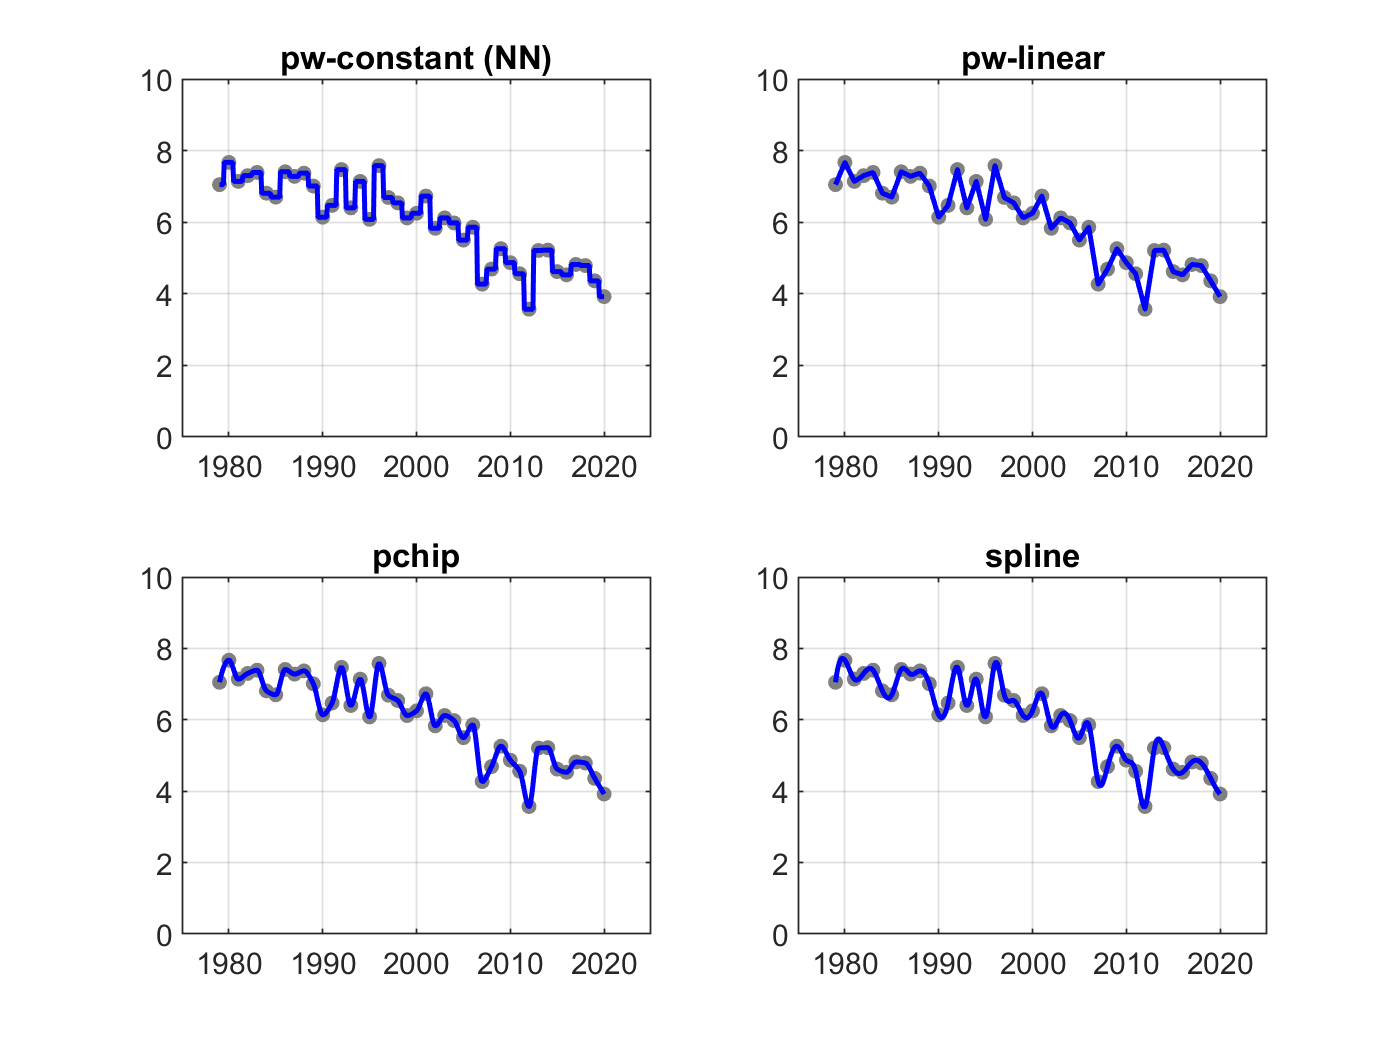

figure; bc = [0.5 0.5 0.5]; 
subplot(2,2,1), plot (Year, SExt, 'o', 'Color', bc, 'MarkerFaceColor', bc, "MarkerSize", 4), hold on, grid on, axis(fa), 
                plot (YearFine, ExtNearestN, 'b', 'LineWidth', 1.5), title('pw-constant (NN)')
subplot(2,2,2), plot (Year, SExt, 'o', 'Color', bc, 'MarkerFaceColor', bc, "MarkerSize", 4), hold on, grid on, axis(fa),  
                plot (YearFine, ExtPWLinear, 'b', 'LineWidth', 1.5), title('pw-linear')
subplot(2,2,3), plot (Year, SExt, 'o', 'Color', bc, 'MarkerFaceColor', bc, "MarkerSize", 4), hold on, grid on, axis(fa), 
                plot (YearFine, ExtPChip, 'b', 'LineWidth', 1.5), title('pchip')
subplot(2,2,4), plot (Year, SExt, 'o', 'Color', bc, 'MarkerFaceColor', bc, "MarkerSize", 4), hold on, grid on, axis(fa), 
                plot (YearFine, ExtSpline, 'b', 'LineWidth', 1.5), title('spline')

EOF.